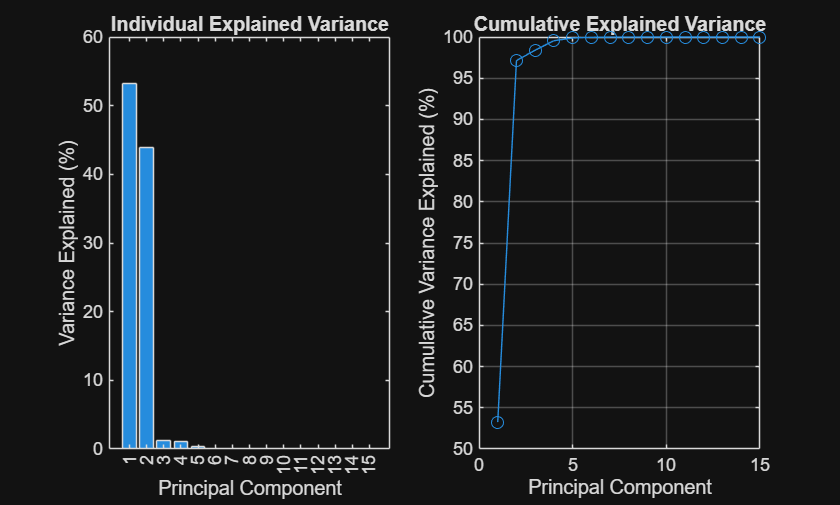

clearvars;
[data, label] = xlsread('Health index1.csv');
data = data(:, 1:15);
X = gpuArray(data);
clear data
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

help pca

 pca - Principal component analysis of raw data
    This MATLAB function returns the principal component coefficients, also
    known as loadings, for the n-by-p data matrix X.

    Syntax
      coeff = pca(X)
      coeff = pca(X,Name,Value)
      [coeff,score,latent] = pca(___)
      [coeff,score,latent,tsquared] = pca(___)
      [coeff,score,latent,tsquared,explained,mu] = pca(___)

    Input Arguments
      X - Input data
        matrix

    Name-Value Arguments
      Algorithm - Principal component algorithm
        'svd' (default) | 'eig' | 'als'
      Centered - Indicator for centering columns
        '

help pca - understand 

see if pattern recognition or regression model

ours is regression

output analysis